assert(endsWith(pwd, "non-ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.num = 2;
EM.inner_radius = [3.75e-3 7.75e-3]; % (m)
EM.outer_radius = [6.00e-3 10.00e-3]; % (m)
EM.length       = [4.00e-3 4.00e-3]; % length (m)
EM.Nturns = [60 60];

EM.z = [5.00e-3 5e-3]; % (m)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 10; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.01 seconds


clear disk r z

Model.conductivity = 1.91e7 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 11.01 seconds


#### Solve in time domain

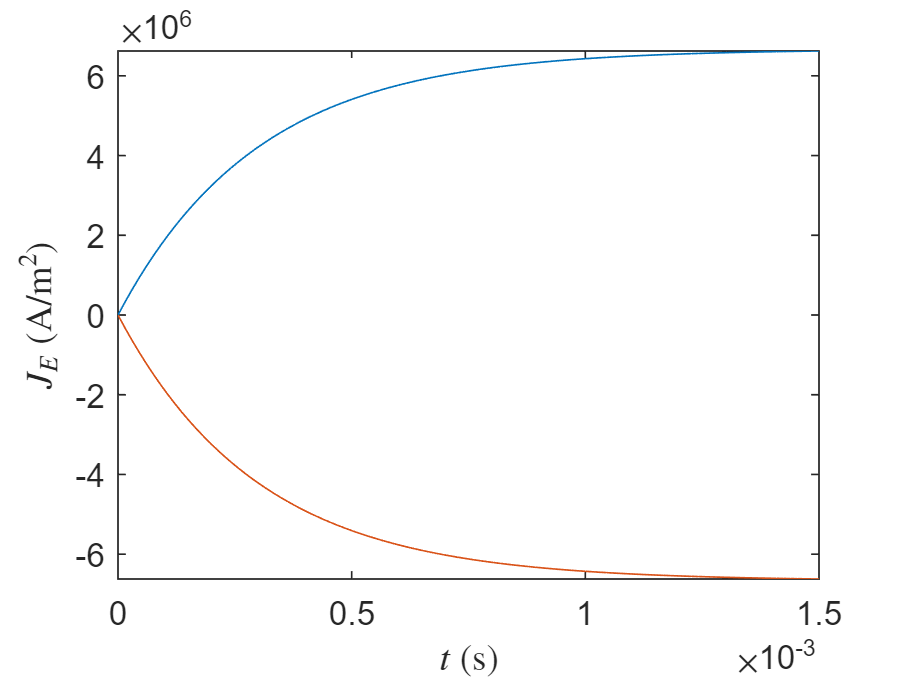

I_E_ss = [1 -1]; % (A)
J_E_ss = I_E_ss .* EM.Nturns ./ ((EM.outer_radius-EM.inner_radius).*EM.length); % (A/m^2)
tau = 3e-4; % (s)

EM.time_domain.current_density = @(t) J_E_ss .* (1 - exp(-t/tau));
EM.time_domain.current_density_diff = @(t) J_E_ss/tau .* exp(-t/tau);
% EM.time_domain.current_density_diff2 = @(t) -J_E_ss/tau^2 * exp(-t/tau);
EM.time_domain.time_span = [0, 1.5e-3]; % (s)

t = linspace(EM.time_domain.time_span(1), EM.time_domain.time_span(end))';
plot(t, EM.time_domain.current_density(t))
ylabel('$J_E$ (A/m$^2$)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss J_E_ss tau t

[Model, EM, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, EM, Sensor);

solve current density took 0.22 seconds
solve magnetic flux density took 0.61 seconds


#### Plot result

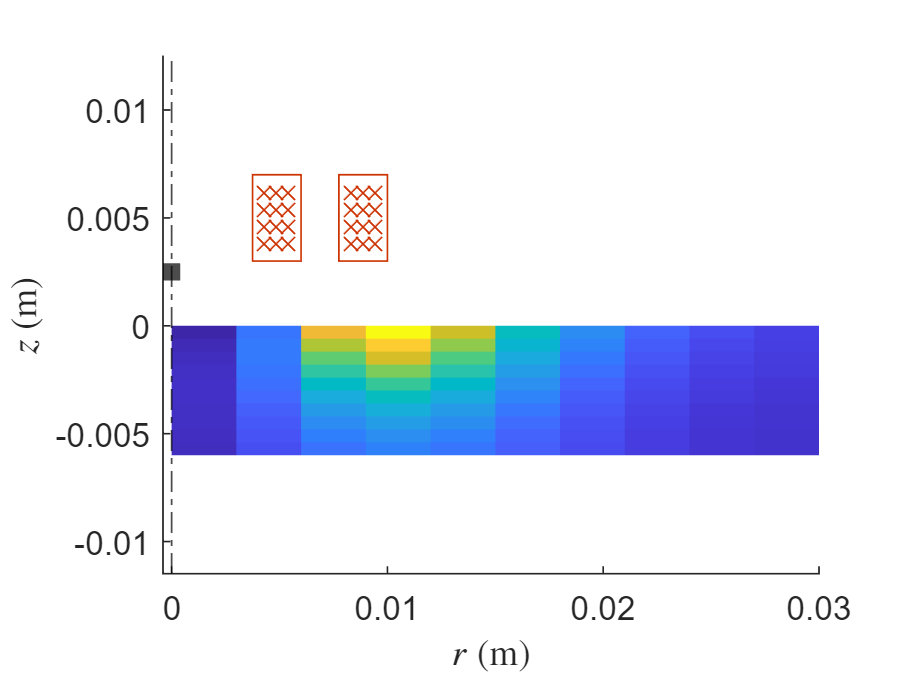

t = 0.3e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
PlotWorld2D(Model, EM, Sensor, abs(Model.time_domain.J(:,:,k)) );

clf
clear t k